%% Rocket Trajectory Sensitivity Analysis
% This script performs sensitivity analysis on a tabletop rocket model,
% examining how changes in key parameters affect the rocket's final position
% at the end of the simulation time.

%% Clear environment
clear all
close all
clc

%% Define baseline parameters
% Initial conditions
v_init = 21;             % Initial velocity magnitude (m/s)
theta_init = 81;         % Initial angle (degrees)
theta = deg2rad(theta_init); % Convert to radians

% Physical parameters
g_base = 9.82;           % Gravity (m/s²)
m0_base = 0.05;          % Initial mass (kg)
k_base = 0.08;           % Mass flow rate (kg/s)
kx_base = 0.001;         % Air resistance coefficient x
ky_base = 0.001;         % Air resistance coefficient y
F_base = 1;              % Force during burn time (N)

% Simulation parameters
t_start = 0;             % Start time (s)
t_burn = 0.08;           % Burn time end (s)
t_end = 4;               % Simulation end time (s)
h = 0.0025;              % Time step size (s)

%% Parameters to vary in sensitivity analysis
% Define parameter ranges (percentage of baseline value)
variation_percent = [-1, 0, 1];
parameter_names = {'Massflödeshastighet (k)', 'Initial hastighet i x-led', 'Initial hastighet i y-led', 'Initial massa (m0)', 'Gravitation (g)'};

% Number of parameters and variations
n_params = length(parameter_names);
n_variations = length(variation_percent);

%% Initialize result matrices
final_x_positions = zeros(n_params, n_variations);
final_y_positions = zeros(n_params, n_variations);
final_vx = zeros(n_params, n_variations);
final_vy = zeros(n_params, n_variations);

%% Run sensitivity analysis
fprintf('Starting sensitivity analysis...\n');

Starting sensitivity analysis...



for p = 1:n_params
    for v = 1:n_variations
        % Copy baseline parameters
        k = k_base;
        m0 = m0_base;
        g = g_base;
        kx = kx_base;
        ky = ky_base;
        F = F_base;
        
        % Calculate initial velocity components from magnitude and angle
        vx0_base = v_init * cos(theta);
        vy0_base = v_init * sin(theta);
        vx0 = vx0_base;
        vy0 = vy0_base;
        
        % Modify the parameter being analyzed
        percent_change = variation_percent(v);
        factor = 1 + percent_change/100;
        
        switch p
            case 1  % Mass flow rate (k)
                k = k_base * factor;
                param_label = sprintf('k = %.7f', k);
            case 2  % Initial velocity x
                vx0 = vx0_base * factor;
                param_label = sprintf('vx0 = %.7f', vx0);
            case 3  % Initial velocity y
                vy0 = vy0_base * factor;
                param_label = sprintf('vy0 = %.7f', vy0);
            case 4  % Initial mass (m0)
                m0 = m0_base * factor;
                param_label = sprintf('m0 = %.7f', m0);
            case 5  % Gravity (g)
                g = g_base * factor;
                param_label = sprintf('g = %.7f', g);
        end
        
        % Run simulation with modified parameter
        [trajectory, times] = simulate_rocket(t_start, t_burn, t_end, h, F, vx0, vy0, m0, k, g, kx, ky);
        
        % Extract the final position data (at the end of simulation)
        final_x = trajectory(1, 695);
        final_y = trajectory(2, 695);
        final_vel_x = trajectory(3, 695);
        final_vel_y = trajectory(4, 695);
        
        % Store results
        final_x_positions(p, v) = final_x;
        final_y_positions(p, v) = final_y;
        final_vx(p, v) = final_vel_x;
        final_vy(p, v) = final_vel_y;
        
        % Progress indicator
        fprintf('Parameter: %s, Variation: %+d%%, Final X: %.7f m, Final Y: %.7f m\n', ...
                parameter_names{p}, percent_change, final_x, final_y);
    end
end

Parameter: Massflödeshastighet (k), Variation: -1%, Final X: 4.7464173 m, Final Y: 16.9039387 m
Parameter: Massflödeshastighet (k), Variation: +0%, Final X: 4.7452504 m, Final Y: 16.8982853 m
Parameter: Massflödeshastighet (k), Variation: +1%, Final X: 4.7440810 m, Final Y: 16.8926184 m
Parameter: Initial hastighet i x-led, Variation: -1%, Final X: 4.6983915 m, Final Y: 16.9008773 m
Parameter: Initial hastighet i x-led, Variation: +0%, Final X: 4.7452504 m, Final Y: 16.8982853 m
Parameter: Initial hastighet i x-led, Variation: +1%, Final X: 4.7920922 m, Final Y: 16.8956696 m
Parameter: Initial hastighet i y-led, Variation: -1%, Final X: 4.7608499 m, Final Y: 16.6780339 m
Parameter: Initial hastighet i y-led, Variation: +0%, Final X: 4.7452504 m, Final Y: 16.8982853 m
Parameter: Initial hastighet i y-led, Variation: +1%, Final X: 4.7297973 m, Final Y: 17.1174316 m
Parameter: Initial massa (m0), Variation: -1%, Final X: 4.7367868 m, Final Y: 16.8587274 m
Parameter: Initial massa (m0), Va

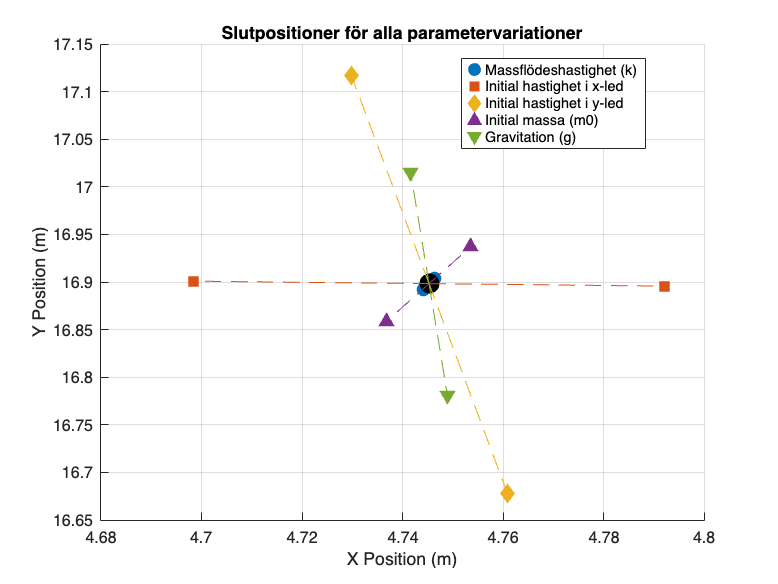


%% Calculate sensitivity coefficients
% Base values (0% variation)
base_idx = find(variation_percent == 0);
base_x = final_x_positions(:, base_idx);
base_y = final_y_positions(:, base_idx);

% Initialize sensitivity matrices
sensitivity_x = zeros(n_params, n_variations);
sensitivity_y = zeros(n_params, n_variations);

% Calculate normalized sensitivity coefficient:
% (percentage change in output) / (percentage change in input)
for p = 1:n_params
    for v = 1:n_variations
        if variation_percent(v) ~= 0
            % For final x position
            if base_x(p) ~= 0
                percent_change_x = (final_x_positions(p,v) - base_x(p)) / abs(base_x(p)) * 100;
                sensitivity_x(p,v) = percent_change_x / variation_percent(v);
            else
                % Handle case where base value is zero
                sensitivity_x(p,v) = NaN;
            end
            
            % For final y position
            if base_y(p) ~= 0
                percent_change_y = (final_y_positions(p,v) - base_y(p)) / abs(base_y(p)) * 100;
                sensitivity_y(p,v) = percent_change_y / variation_percent(v);
            else
                % Handle case where base value is zero
                sensitivity_y(p,v) = NaN;
            end
        else
            % No sensitivity at base value (avoid division by zero)
            sensitivity_x(p,v) = 0;
            sensitivity_y(p,v) = 0;
        end
    end
end

%% Visualization of Results




% 6. Create a scatter plot of all final positions
figure(6);
hold on;
colors = lines(n_params);  % More distinct colors than 'rgbkmcy'
markers = ['o', 's', 'd', '^', 'v', '*', '+'];  % Enough distinct markers

legend_handles = gobjects(n_params, 1);  % Preallocate graphics handles
param_legend = cell(n_params, 1);

for p = 1:n_params
    for v = 1:n_variations
        h = plot(final_x_positions(p,v), final_y_positions(p,v), ...
                 markers(mod(p-1, length(markers))+1), ...
                 'MarkerSize', 8, ...
                 'MarkerEdgeColor', colors(p,:), ...
                 'MarkerFaceColor', colors(p,:));
        % Store one handle per parameter for legend (use first variation)
        if v == base_idx
            legend_handles(p) = h;
        end
    end
    param_legend{p} = parameter_names{p};
end

% Plot base case as large black dot
plot(base_x(1), base_y(1), 'ko', 'MarkerSize', 12, 'MarkerFaceColor', 'k');

% Connect lines from base to variations
for p = 1:n_params
    for v = 1:n_variations
        if v ~= base_idx
            line([base_x(1), final_x_positions(p,v)], ...
                 [base_y(1), final_y_positions(p,v)], ...
                 'Color', colors(p,:), 'LineStyle', '--', 'LineWidth', 0.5);
        end
    end
end

legend(legend_handles, param_legend, 'Location', 'best');
title('Slutpositioner för alla parametervariationer');
xlabel('X Position (m)');
ylabel('Y Position (m)');
grid on;
hold off;



%% Summary of Results
fprintf('\n=== Sensitivity Analysis Summary ===\n');


=== Sensitivity Analysis Summary ===


fprintf('Base case final X position: %.7f m\n', base_x(1));

Base case final X position: 4.7452504 m


fprintf('Base case final Y position: %.7f m\n', base_y(1));

Base case final Y position: 16.8982853 m



% Find most and least sensitive parameters for final X position
[max_sens_x, max_idx_x] = max(max(abs(sensitivity_x(:,variation_percent~=0)), [], 2));
[min_sens_x, min_idx_x] = min(max(abs(sensitivity_x(:,variation_percent~=0)), [], 2));

fprintf('\nFor final X position:\n');


For final X position:


fprintf('Most sensitive parameter: %s (max sensitivity: %.2f)\n', ...
        parameter_names{max_idx_x}, max_sens_x);

Most sensitive parameter: Initial hastighet i x-led (max sensitivity: 0.99)


fprintf('Least sensitive parameter: %s (max sensitivity: %.2f)\n', ...
        parameter_names{min_idx_x}, min_sens_x);

Least sensitive parameter: Massflödeshastighet (k) (max sensitivity: 0.02)



% Find most and least sensitive parameters for final Y position
[max_sens_y, max_idx_y] = max(max(abs(sensitivity_y(:,variation_percent~=0)), [], 2));
[min_sens_y, min_idx_y] = min(max(abs(sensitivity_y(:,variation_percent~=0)), [], 2));

fprintf('\nFor final Y position:\n');


For final Y position:


fprintf('Most sensitive parameter: %s (max sensitivity: %.2f)\n', ...
        parameter_names{max_idx_y}, max_sens_y);

Most sensitive parameter: Initial hastighet i y-led (max sensitivity: 1.30)


fprintf('Least sensitive parameter: %s (max sensitivity: %.2f)\n', ...
        parameter_names{min_idx_y}, min_sens_y);

Least sensitive parameter: Initial hastighet i x-led (max sensitivity: 0.02)



%% Helper Functions

function [z, t] = simulate_rocket(t_start, t_burn, t_end, h, F, vx0, vy0, m0, k, g, kx, ky)
    % Initial conditions
    x0 = 0;
    y0 = 0;
    
    % Generate time values
    t = t_start:h:t_end;
    N = length(t);
    
    % Initialize solution matrix [x, y, vx, vy]
    z = zeros(4, N);
    z(:, 1) = [x0; y0; vx0; vy0];
    
    % Runge-Kutta integration
    for i = 1:N-1
        t_current = t(i);
        z_current = z(:, i);
        
        % Four steps of RK4 method
        k1 = rocket_ode(t_current, z_current, F, t_burn, m0, k, g, kx, ky);
        k2 = rocket_ode(t_current + h/2, z_current + (h/2)*k1, F, t_burn, m0, k, g, kx, ky);
        k3 = rocket_ode(t_current + h/2, z_current + (h/2)*k2, F, t_burn, m0, k, g, kx, ky);
        k4 = rocket_ode(t_current + h, z_current + h*k3, F, t_burn, m0, k, g, kx, ky);
        
        % Update solution
        z(:, i+1) = z_current + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
        
        % For this analysis, we want to run the full simulation time
        % regardless of whether the rocket hits the ground
    end
end

function dzdt = rocket_ode(t, z, F_val, t_burn, m0, k, g, kx, ky)
    % Extract state variables
    vx = z(3);     % Velocity x
    vy = z(4);     % Velocity y
    
    % Calculate current mass
    if t <= t_burn
        m = m0 - k*t;
    else
        m = m0 - k*t_burn;
    end
    
    % Calculate thrust force
    if t <= t_burn
        F = F_val;
    else
        F = 0;
    end
    
    % Calculate angle
    phi = atan2(vy, vx);  % Using atan2 for correct quadrant
    
    % Calculate speed
    V = sqrt(vx^2 + vy^2);
    
    % Differential equations
    dzdt = zeros(4, 1);
    dzdt(1) = vx;
    dzdt(2) = vy;
    dzdt(3) = (F*cos(phi) - kx*vx*V)/m;
    dzdt(4) = (F*sin(phi) - ky*vy*V)/m - g;
end